# Optimizing a Faust

When a Faust  object is instantiated it might be possible to optimize its structure or configuration before using it elsewhere. It applies in all cases,  whether you gave explicitly the matrices to define the Faust or you  obtained it through a FAµST algorithm or an operation like  Faust-slicing. Indeed, several operations are available in the FAµST API to optimize a  Faust object, in memory space or in computation time.

In this notebook, we'll present three functions that aim at fulfilling these tasks:

1. Faust.optimize_memory

2. Faust.optimize_time

3. Faust.pruneout

## 1. Faust.optimize_memory

As you probably already know, a Faust can be composed of dense or sparse  factors. In the FAµST C++ core, a dense matrix is encoded as a  column-major order array in memory while a sparse matrix follows the [CSR format](https://docs.scipy.org/doc/scipy/reference/generated/scipy.sparse.csr_matrix.html). Although this is not memory efficient, it is totally possible to encode a sparse matrix in the dense format and conversely a dense matrix in the CSR format. There is no reason to do this but in many situations you might end up with a Faust encoded in a non-optimal format in your code.

That's where the `Faust.optimize_memory` function comes up,  it takes a Faust and gives you back a new one for which the format of  each factor is ensured to be memory efficient. It means that depending  on the number of nonzeros of the considered matrix, the format will be chosen by the function to minimize the memory used for the whole Faust.

Let's show this principle with a very simple example:

I build a Faust creating my own CSR matrix using [scipy](https://www.scipy.org/) and a dense matrix using a [numpy](https://numpy.org/) array. On purpose I choose to create a CSR matrix of size NxN whose nnz is equal to N^2 (something that obviously must be encoded as a numpy  array) and likewise I create a numpy array of size NxN whose nnz is 1  (here again the format is not well chosen because a CSR matrix would be far lighter in memory).

N = 64;
S = sprand(N, N, 1); % density = 1 <=> nnz = N^2
M = zeros(N,N);
M(1,1) = 1;
% now create the Faust
import matfaust.Faust
F = Faust({S, M});  % S is in CSR format, M is in column-major order array


Let's check the size (in bytes) of the Faust F we've just created.

nbytes(F)

Now use the `optimize_memory` function to get a memory-efficient Faust equal to F and check its new size.

G = optimize_memory(F);
nbytes(G)

Let us verify that F and G are really equal.

all(all(full(F) == full(G)))

As you can see the memory consumed by F is uselessly greater than the memory used for G. What `optimize_memory` did is simply to use a sparse CSR format for M which is formally a  sparse matrix (it contains a few nonzeros for a lot of zeros), and  convert S to an array because a dense matrix consumes more in memory if  it is encoded as a sparse CSR matrix. The change of format can be verified printing the Faust-s:

F
G

You'll find the API documentation of `Faust.optimize_memory` [here](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a694a5e9fda6a5d05f83da8f23827cb41).

## 2. Faust.optimize_time

The goal of `Faust.optimize_time` is not to be memory efficient like `optimize_storage` does but rather time efficient. The problem to consider here is the [matrix chain problem](https://en.wikipedia.org/wiki/Matrix_chain_multiplication). If you want to multiply an arbitrary number n of matrices, because of  the associative property of the matrix product, you have many ways to do it. In fact, as many ways as number of possible parenthesis pair positions in the product. This number of possible positions is given by the [catalan number](https://en.wikipedia.org/wiki/Catalan_number) $C_{n-1}$. From an optimization point of view the question is what set of positions would be the most efficient to compute the matrix product?  Or equivalently which order of matrix products will allow to compute the whole product of n matrices in the minimum time?

That is the problem `optimize_time` tackles with several solutions:

- The `DYNPROG` method which is the [classic dynamic programming approach](https://en.wikipedia.org/wiki/Matrix_chain_multiplication#A_dynamic_programming_algorithm) to solve the problem. A good reference to look at is: **Cormen, Thomas H; Leiserson, Charles E; Rivest, Ronald L; Stein, Clifford (2001). "15.2: Matrix-chain multiplication". Introduction to  Algorithms. Second Edition. MIT Press and McGraw-Hill. pp. 331–338. **Note that neverthless the method implemented in FAµST is an extended  version of the one discussed in the given reference because FAµST takes  also into account the complexity of the sparse matrices that have to be computed differently from the complexity of a dense matrix product.

- FAµST provides other methods in exprimental packages, basically these methods use the Torch library as a backend to compute the product  with some variations.

Anyway, `optimize_time` is able to select the best method available for your Faust. It's capable to benchmark these methods automatically on `Faust.full` or on a Faust-matrix product. Note that the GPU backend is not yet included in the benchmark.

That's what the following examples show:

F = Faust('F_DYNPROG.mat');
dat = load('M_DYNPROG.mat');
M = dat.M;
G = optimize_time(F, 'mat', M);

The code above is creating a Faust `F` based on the file `F_DYNPROG.mat` (provided by the FAµST data archive). Likewise a matrix `M` based on the file `M_DYNPROG.mat` is created. As you can guess from the file names the best method found by `optimize_time` is the `DYNPROG` method. Hence `G` is a version of the Faust `F` for which the `DYNPROG` method will be used to compute `full(G)` or `G*M` (for any matrix `M`). By default, `F` is configured to compute the both of these products by simply multiplying the matrices from the right to the left (aka `DEFAULT_L2R`).

Note that M is passed as `mat` argument of `optimize_time` which in consequence runs the benchmark on `F@M` (without `mat` argument, `optimize_time` runs the benchmark on `full(F)`).

Now let us compare the computation times respectively for F and G.

timeit(@() full(F))
timeit(@() full(G))
timeit(@() F*M)
timeit(@() G*M)

G is definitely faster than F!

For further details about `Faust.optimize_time`, you can look at the API reference [here](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classpyfaust_1_1Faust.html#a0348f4cfe22b920fa741860773240174https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a3c82b574dc1fab605d350d28140e47b7) and maybe the [FaustMulMode](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1FaustMulMode.html) too for a tour of all methods available.

## 3. Faust.pruneout

As `Faust.optimize_time`, the member function `Faust.pruneout` is mainly dedicated to optimize the Faust product time (for `Faust.full()` or Faust-matrix product). Basically, this function removes zero rows  (resp. columns) and corresponding columns (resp. rows) in consecutive pairs of factors. The following figure illustrates a basic iteration of pruneout on a  product AB. The submatrices covered by the blue grid are removed by the  pruneout operation because the row block of B is composed only of zeros. Hence the resulting product A'B' is less costly.

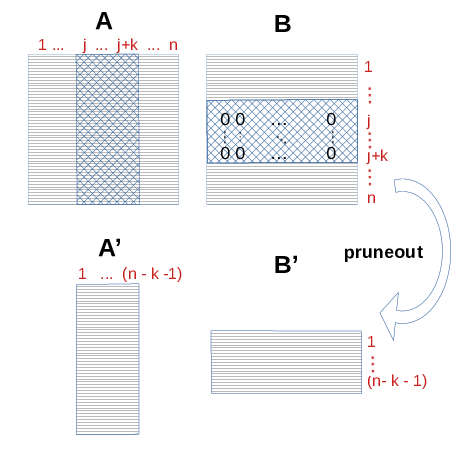

The example above is trivial but when a Faust contain many factors  including very sparse matrices, the benefit can be quite significant. The reason why is that `pruneout` repeats the removal operation iteratively until there is no zero column/row eligible to this operation anymore.

Note that of course the resulting Faust gives the same full matrix (i.e. `Faust.full` must give the same result after a `Faust.pruneout`).

In the next section of code I show with a figure how a sliced DFT Faust can benefit of `Faust.pruneout` in terms of computation time.

times_Fsub = [];
times_Fpr = [];
n_exps = 5:14;
N = 3;
k = 10;
for i=n_exps
    n = 2^i;
    F = matfaust.dft(n);
    I = randperm(n);
    I = sort(I(1:k));
    Fsubset = F(:,I);
    Fpruned = pruneout(Fsubset);
    x = rand(n, 1);
    xsubset = x(I);
    time = [];
    for i=1:N
        time = [ time timeit(@() Fsubset*xsubset)];
    end
    times_Fsub = [ times_Fsub median(time)];
    time = [];
    for i=1:N
        time = [ time timeit(@() Fpruned*xsubset)];
    end
    times_Fpr = [ times_Fpr median(time)];

    
end
legend()
semilogy(n_exps, times_Fsub, '-+', n_exps, times_Fpr, '-o');
grid('on');
legend('Fsubset*xsubset', 'Fpruned*xsubset')
xlabel('n\_exps');
ylabel('time (s)');

**Note:** this live script was executed using the following matfaust version:

matfaust.version()